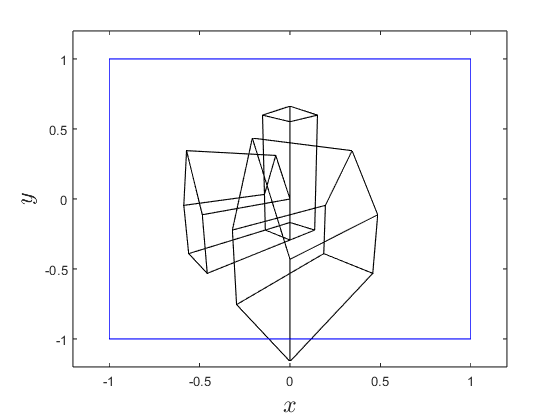

clear

% Load screen space coordinates
load('screen_space_coords.mat')

% Clip screen space co-ordinates
[Vclipped, Fclipped] = clipped_space(Vscreen, F);

% Save clipped space co-ordinates
save('clipped_space_co-ordinates', "Vclipped", "Fclipped");

% Plot screen space (from viewing position)
figure()
h1 = axes;
patch('Vertices', Vscreen([1,3,2],:)', 'Faces', F, FaceColor='w', FaceAlpha=0)
patch('Vertices', Vcube(1:3,:)', 'Faces', Fcube, FaceAlpha=0, EdgeColor="blue")

xlabel('$x$', 'Interpreter', 'latex', 'FontSize', 18)
ylabel('$z$', 'Interpreter', 'latex', 'FontSize', 18)
zlabel('$y$', 'Interpreter', 'latex', 'FontSize', 18)
set(h1, 'Ydir', 'reverse')
view(0,0)
axis([-1.2, 1.2, -1.2, 1.2, -1.2, 1.2])
box on

exportgraphics(gcf,'../images/clipped_space_example_1.png','Resolution',300) 

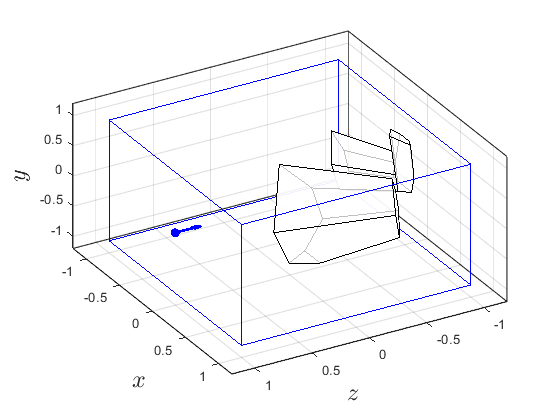

% Plot camera space viewed from the side
figure()
h1 = axes;
patch('Vertices', Vclipped([1,3,2],:)', 'Faces', Fclipped, FaceColor='w', FaceAlpha=0.75)
patch('Vertices', Vcube(1:3,:)', 'Faces', Fcube, FaceAlpha=0, EdgeColor="blue")
hold on
plot3(0,1,0,'bo',MarkerFaceColor='b')
quiver3(0,1,0,0,-0.25,0, 'b', LineWidth=2, MaxHeadSize=1)
hold off

xlabel('$x$', 'Interpreter', 'latex', 'FontSize', 18)
ylabel('$z$', 'Interpreter', 'latex', 'FontSize', 18)
zlabel('$y$', 'Interpreter', 'latex', 'FontSize', 18)
set(h1, 'Ydir', 'reverse')
view(60,45)
axis([-1.2, 1.2, -1.2, 1.2, -1.2, 1.2])
box on
grid
exportgraphics(gcf,'../images/clipped_space_example_2.png','Resolution',300) 

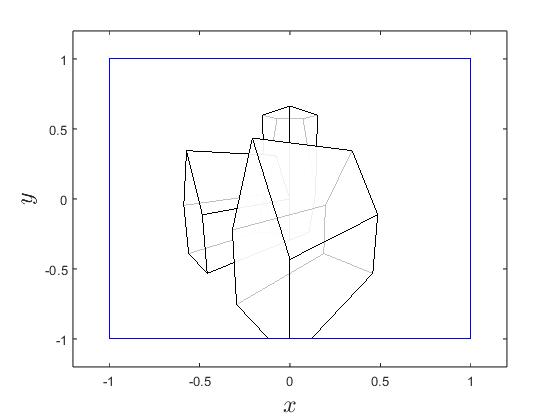

% Plot camera space viewed looking down the z-axis.
figure()
h1 = axes;
patch('Vertices', Vclipped([1,3,2],:)', 'Faces', Fclipped, FaceColor='w', FaceAlpha=0.75)
patch('Vertices', Vcube(1:3,:)', 'Faces', Fcube, FaceAlpha=0, EdgeColor="blue")

xlabel('$x$', 'Interpreter', 'latex', 'FontSize', 18)
ylabel('$z$', 'Interpreter', 'latex', 'FontSize', 18)
zlabel('$y$', 'Interpreter', 'latex', 'FontSize', 18)
set(h1, 'Ydir', 'reverse')
view(0,0)
axis([-1.2, 1.2, -1.2, 1.2, -1.2, 1.2])
box on
view(0,0)

exportgraphics(gcf,'../images/clipped_space_example_3.png','Resolution',300) 

function [Vclipped, Fclipped] = clipped_space(V, F)

% Define cube region points and normal vectors
P = [ -1, -1,  1,  1, -1, 1 ; 
      -1, -1,  1,  1, -1, 1 ; 
       1,  1, -1, -1,  1, -1 ];
n = [ 0,  0, -1, 0, 1,  0 ;  
      1,  0,  0, 0, 0, -1 ; 
      0, -1,  0, 1, 0,  0 ];

% Loop through the polygons in F
Vclipped = V;
Fclipped = [];
for poly = 1 : size(F, 1)

    % Loop through the edges of the clipping cube
    outputlist = F(poly, :);
    for edge = 1 : size(P,2)
        inputlist = outputlist;
        outputlist = [];

        for i = 1 : length(inputlist)
            current = inputlist(i);
            if i > 1
                previous = inputlist(i - 1);
            else
                previous = inputlist(end);
            end

            % Calculate intersection point
            dcurrent = dot(Vclipped(1:3,current) - P(:,edge), n(:,edge));
            dprevious = dot(Vclipped(1:3,previous) - P(:,edge), n(:,edge));
            if dcurrent - dprevious ~= 0
                t = dprevious / (dprevious - dcurrent);
                intersection = [Vclipped(1:3,previous) + t * (Vclipped(1:3,current) - Vclipped(1:3,previous)) ; 1];
            end

            % Check if polygon edge crosses clipping cube edge
            if dcurrent > 0 
                % if previous point is outside add intersection to output list
                if dprevious < 0 
                    Vclipped = [Vclipped, intersection];
                    outputlist = [outputlist, size(Vclipped, 2)];
                end
                outputlist = [outputlist, current];

            elseif dprevious > 0
                % current point is outside and previous point is inside so add
                % intersection to output list
                Vclipped = [Vclipped, intersection];
                outputlist = [outputlist, size(Vclipped, 2)];
            end
        end
    end

    % If outputlist is non-empty add to Fclipped
    if isempty(outputlist) == 0
        nclippedverts = length(outputlist);

        if isempty(Fclipped)
            Fclipped = outputlist;
            maxverts = length(outputlist);
        else
            if maxverts < nclippedverts
                % Pad out Fclipped if number of clipped vertices is greater
                % than current maxverts
                Fclipped = [Fclipped, zeros(size(Fclipped, 1), nclippedverts - maxverts)];
                Fclipped(:,maxverts + 1 : end) = Fclipped(:, maxverts);
                maxverts = nclippedverts;

            elseif maxverts > length(outputlist)
                % Pad out outputlist if number of clipped vertices is less than
                % current maxverts
                outputlist = [outputlist, ones(1,maxverts - nclippedverts) * outputlist(end)];
            end

            % Add outputlist to Fclipped
            Fclipped = [Fclipped ; outputlist];
        end
    end

end

end